### Применение класификатора к полседовательности

#### Обучение класификатора

clear all
close all

load('const.mat')   % Load consts as NFFT, ds, NOTES...
load('data.mat')    % Load data object with 1-noise, 2-85 notes

Y = zeros(N*NOTES, 1);
X = zeros([N*NOTES, NFFT+N_zero]);    % С интерполяцией
% X = zeros([N*NOTES, NFFT]);         % Без интерполяции

for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),NFFT,[])';
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% OPTIONAL
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Window function
    % Add Hamming window
    h = hamming(NFFT)';
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end

clear data

Разделяю данные на тестовые и тренировочные

cv = cvpartition(Y,"HoldOut",0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear z X Y y

Нахожу спектры этих данных и урезаю их (беру 1/ds от спектра). А так же нормализирую спектры

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

% XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
% XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
% XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

% Normalization of data
% XTest_ds  = XTest_ds ./ max(XTest_ds, [], 2);   %sum(XTest_ds, 2);
XTrain_ds = XTrain_ds ./ max(XTrain_ds, [], 2); %sum(XTrain_ds, 2);

clear XTrain XTest XTest_spec XTrain_spec

tic
Mdl_freq = fitcecoc(XTrain_ds,YTrain);
toc
save('SVM_model.mat', 'Mdl_freq')

#### Проверяю модель на последовательности

clear XTest_ds XTrain_ds
load('SVM_model.mat')

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Examples\My_mario.wav";
[seq, Fs] = audioread(path);

load('Yreal_notes.mat') 

[ATest, STest] = size(seq);
ATest = floor(ATest / NFFT);

% Разделяю на куски по NFFT
% Интерполирую спектры (добавляю нули)
s = zeros([ATest, NFFT+N_zero]);
for i = 1:ATest
    
    n1 = (i-1)*NFFT + 1;
    n2 = i*NFFT;
    
    h = hamming(NFFT);
    seqh = seq(n1:n2) .* h;
    
    s(i, 1:NFFT) = seqh;
end
s_spec = abs(fft(s'))';
clear s
s_spec = s_spec(:,vtest);
s_spec = s_spec ./ max(s_spec, 2);

% my_notes = zeros([ATest 1]);

tic
label = predict(Mdl_freq, s_spec);
toc

Elapsed time is 39.595485 seconds.


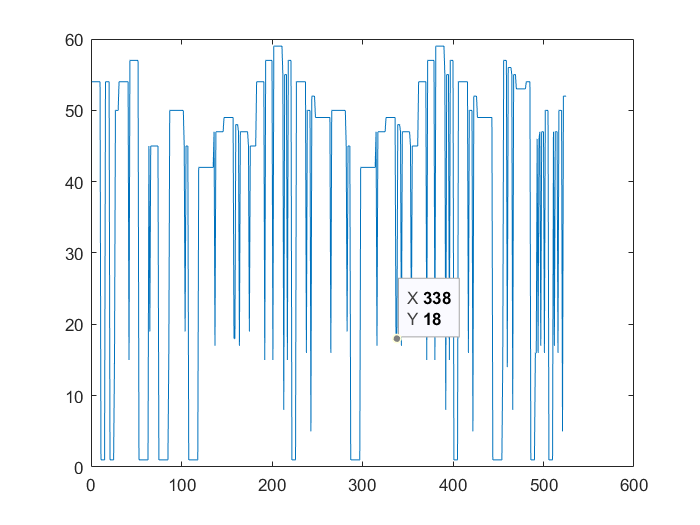


for i = 1:length(label)
    if label(i) == 85
        label(i) = 1;
    end
end
% 
% for j = 1:ATest
%     
%     test_sig = s_spec(j, :);
%     test_label = Yreal_notes(j);
%     
%     label = predict(Mdl_freq, test_sig);
%     
%     if label == 85
%         note = 1;
%     else
%         note = label;
%     end
%     
%     if note(1) ~= test_label
%         p_error = p_error + 1;
%     end
%     
%     my_notes(j) = note(1);% Sometimes it returns 1x88 zeros vector      
%     
% end

load('Yreal_notes.mat')

figure
plot(Yreal_notes)
hold on
plot(label)

hold off

p_error = 0;
for i = 1:length(label)
    if label(i) ~= Yreal_notes(i)
        p_error = p_error + 1;
    end
end

p_error = 100 * p_error / ATest